syms K A u_r u_l  DJK DJI u_i u_j u_k u_m
F = (- 0.5*DJK*(u_j - u_i) + 0.5*DJI*(u_j - u_k));

## **The expression for DIJ is defined as follow:**

# 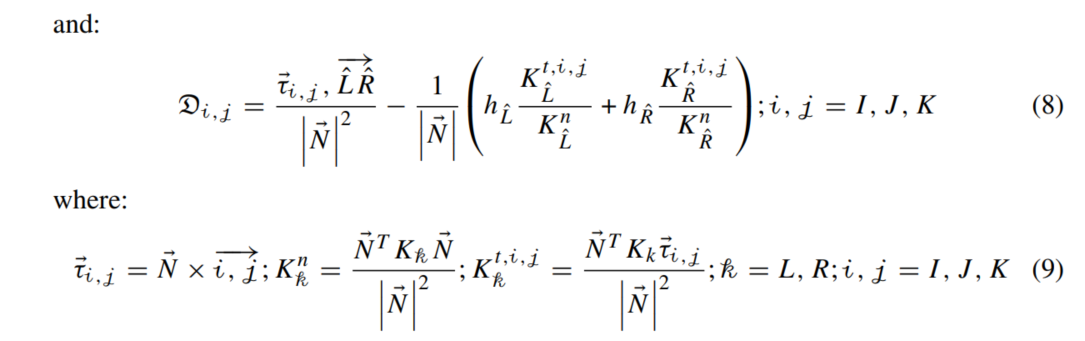

# **Total Flux Expression for Tetrahedron**

**The generalization of the TPFA terms of the MPFA-D is trivial. Therefore, we only need to study the CDT terms.**

**We start by defining the CDT terms of two tetrahedron sharing a common face IJK**

#### **IJK**

Fm = -K*A*collect(F,[u_r u_l u_i u_j u_k])

$$Fm = -A\,K\,\left(\frac{\mathrm{DJK}}{2}\,u_{i}+\left(\frac{\mathrm{DJI}}{2}-\frac{\mathrm{DJK}}{2}\right)\,u_{j}+\left(-\frac{\mathrm{DJI}}{2}\right)\,u_{k}\right)$$

The idea here is to generalize is to devide the area A of a polygon using as an auxiliary node the center of A. It exists a point C inside this polygon that divides the quadrilateralface IJKM into 4 parts with equal areas A/4  ICJ, JCK, KCM and MI/

**ICJ**

syms DCK DCM DCJ DCI DCJ u_c A A_1 A_2 A_3 A_4
% I J
F_1 = (-0.5*DCJ*(u_c - u_i) + 0.5*DCI*(u_c - u_j));
F_IJ = -K*A/4 *collect(F_1,[u_r u_l u_i u_c u_j])

$$F\_IJ = -\frac{A\,K\,\left(\frac{\mathrm{DCJ}}{2}\,u_{i}+\left(\frac{\mathrm{DCI}}{2}-\frac{\mathrm{DCJ}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCI}}{2}\right)\,u_{j}\right)}{4}$$

## Flux in JCK

**JCK**

F_2 = (- 0.5*DCK*(u_c - u_j) + 0.5*DCJ*(u_c - u_k));
F_JK = -K*A/4*collect(F_2,[u_r u_l u_j u_c u_k u_m])

$$F\_JK = -\frac{A\,K\,\left(\frac{\mathrm{DCK}}{2}\,u_{j}+\left(\frac{\mathrm{DCJ}}{2}-\frac{\mathrm{DCK}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCJ}}{2}\right)\,u_{k}\right)}{4}$$

## Flux in KCM

**KCM**

F_3 = (- 0.5*DCM*(u_c - u_k) + 0.5*DCK*(u_c - u_m));
F_KM = -K*A/4*collect(F_3,[u_k u_c u_m])

$$F\_KM = -\frac{A\,K\,\left(\frac{\mathrm{DCM}}{2}\,u_{k}+\left(\frac{\mathrm{DCK}}{2}-\frac{\mathrm{DCM}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCK}}{2}\right)\,u_{m}\right)}{4}$$

## Flux in MCI

**MCI**

syms DCM
F_4 = (- 0.5*DCI*(u_c - u_m) + 0.5*DCM*(u_c - u_i));
F_MI = -K*A/4*collect(F_4,[u_m, u_c u_i])

$$F\_MI = -\frac{A\,K\,\left(\frac{\mathrm{DCI}}{2}\,u_{m}+\left(\frac{\mathrm{DCM}}{2}-\frac{\mathrm{DCI}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCM}}{2}\right)\,u_{i}\right)}{4}$$

## Flux CDT in IJKM

**IJKM**

**F = F_IJ + F_JK + F_KM + F_MI**

**where**

$A$** = **$A_1 + A_2 + A_3 + A_4$

%K I
%disp("K I")
F_total =  F_IJ + F_JK + F_KM + F_MI 

$$F\_total = -\frac{A\,K\,\left(\frac{\mathrm{DCJ}}{2}\,u_{i}+\left(\frac{\mathrm{DCI}}{2}-\frac{\mathrm{DCJ}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCI}}{2}\right)\,u_{j}\right)}{4}-\frac{A\,K\,\left(\frac{\mathrm{DCK}}{2}\,u_{j}+\left(\frac{\mathrm{DCJ}}{2}-\frac{\mathrm{DCK}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCJ}}{2}\right)\,u_{k}\right)}{4}-\frac{A\,K\,\left(\frac{\mathrm{DCI}}{2}\,u_{m}+\left(\frac{\mathrm{DCM}}{2}-\frac{\mathrm{DCI}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCM}}{2}\right)\,u_{i}\right)}{4}-\frac{A\,K\,\left(\frac{\mathrm{DCM}}{2}\,u_{k}+\left(\frac{\mathrm{DCK}}{2}-\frac{\mathrm{DCM}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCK}}{2}\right)\,u_{m}\right)}{4}$$

%F_total = collect(expand(F_total), u_c)
F_n = (1/4)*(collect(expand(4*F_total), [u_i u_j u_k u_m u_c K A]))

$$F\_n = -\frac{A\,K\,u_{i}\,\left(\frac{\mathrm{DCJ}}{2}-\frac{\mathrm{DCM}}{2}\right)}{4}+\frac{A\,K\,u_{j}\,\left(\frac{\mathrm{DCI}}{2}-\frac{\mathrm{DCK}}{2}\right)}{4}+\frac{A\,K\,u_{k}\,\left(\frac{\mathrm{DCJ}}{2}-\frac{\mathrm{DCM}}{2}\right)}{4}-\frac{A\,K\,u_{m}\,\left(\frac{\mathrm{DCI}}{2}-\frac{\mathrm{DCK}}{2}\right)}{4}$$

dot(CJ,LR) - dot(CM,LR) = dot(CJ-CM,LR) = dot( MC+CJ) = dot(MJ)